# 21960197 向平 Assignment

# EX 2.5

Carry out the steps of Computer Problem 2 for (a) Gauss–Seidel Method and (b) SOR with ω = 1.5.

% Gauss-Seidel method
% matrix setup
n = 100;
e = ones(n,1);
A = spdiags([e,2*e,e],-1:1,n,n);
b = zeros(n,1);
b(1) = 1;
b(n) = -1;
x_c = ones(n,1);
x_c(2:2:end) = -1;
x = zeros(n,1);
iteration = 1;
while  norm((x_c-x),"inf")>10^(-2)
    iteration = iteration +1;
    for i=1:n
        if i==1
            x(i) = (1-x(i+1))/2;
        elseif i==n
            x(i) = (-1-x(i-1))/2;
        else
            x(i) = (-x(i-1)-x(i+1))/2;
        end   
    end
end

x

x =     0.9997
   -0.9994
    0.9990
   -0.9987
    0.9984
   -0.9981
    0.9978
   -0.9975
    0.9972
   -0.9969


iteration

iteration = 5011

backward_error = norm((A*x-b),"inf")

backward_error = 9.6744e-06

% SOR method
% matrix setup
w = 1.5;
n = 100;
e = ones(n,1);
A = spdiags([e,2*e,e],-1:1,n,n);
b = zeros(n,1);
b(1) = 1;
b(n) = -1;
x_c = ones(n,1);
x_c(2:2:end) = -1;
x = zeros(n,1);
iteration = 1;
while  norm((x_c-x),"inf")>10^(-3)
    iteration = iteration +1;
    for i=1:n
        if i==1
            x(i) = (1-w)*x(i) + w*(1-x(i+1))/2;
        elseif i==n
            x(i) = (1-w)*x(i) + w*(-1-x(i-1))/2;
        else
            x(i) = (1-w)*x(i) + w*(-x(i-1)-x(i+1))/2;
        end   
    end
end
x

x =     1.0000
   -0.9999
    0.9999
   -0.9999
    0.9998
   -0.9998
    0.9998
   -0.9997
    0.9997
   -0.9997


iteration

iteration = 2461

backward_error = norm((A*x-b),"inf")

backward_error = 9.7363e-07

# EX 2.6

Let A be the n × n matrix with n = 1000 and entries $A\left(i,i\right)=i,A\left(i,i+1\right)=A\left(i+1,i\right)=\frac{1}{2},A\left(i,i+2\right)=A\left(i+2,i\right)=\frac{1}{2}$ , for all i that fit within the matrix. (a) Print the nonzero structure spy(A). (b) Let $x_e$ be the vector of n ones. Set $b={A\;x}_e$, and apply the Conjugate Gradient Method, without preconditioner, with the Jacobi preconditioner, and with the Gauss–Seidel preconditioner. Compare errors of the three runs in a plot versus step number.

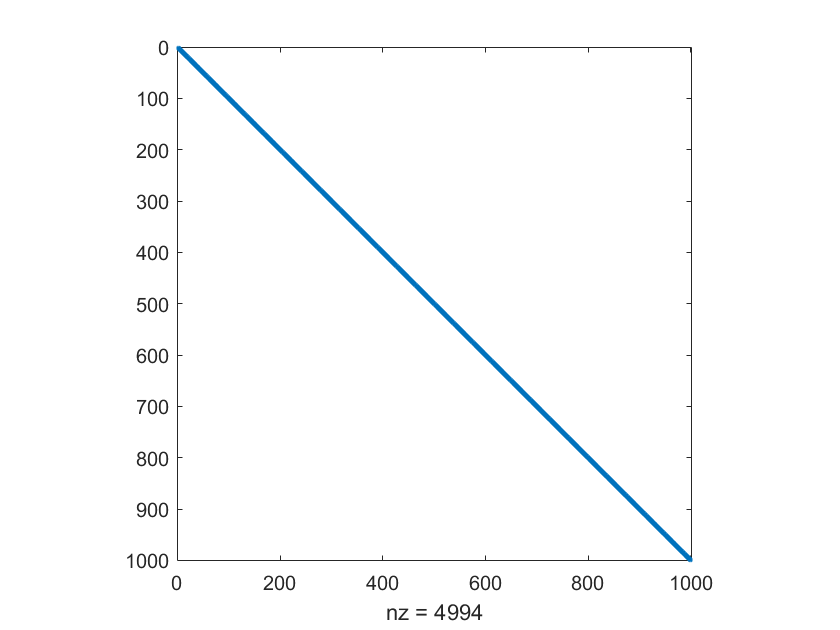

% matrix setup
w = 1.5;
n = 1000;
e = ones(n,1);
A = spdiags([0.5*e,0.5*e,e,0.5*e,0.5*e],-2:2,n,n);
spy(A)

% without preconditioner
xe = ones(n,1);
b = A*xe;
x = 0.5*ones(n,1);
x_iter_1 = zeros(n,4);
d = b-A*x;
r = b-A*x;
for i=1:n
    if r==0
        break;
    end
    a = (d'*r)/(d'*A*d);
    x = x+a*d;
    r = b-A*x;
    beta = -1*(d'*A*r)/(d'*A*d);
    d = r+beta*d;
    if mod(i, 250)==0
        x_iter_1(:,i/250) = x;
    end
end
x

x =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


% with Jacobi preconditioner
xe = ones(n,1);
b = A*xe;
M = eye(n,n);
M_ = inv(M);
x = 0.5*ones(n,1);
x_iter_2 = zeros(n,4);
r = b-A*x;
%d = M_*r;  % inv(M)*r = M\r
d = M\r;
z = d;
for i=1:n
    if r==0
        break;
    end
    a = (r'*z)/(d'*A*d);
    x = x + a*d;
    r_old = r;
    z_old = z;
    r = r - a*A*d;
    %z = M_*r;
    z = M\r;
    beta = (r'*z)/(r_old'*z_old);
    d = z+beta*d;
    if mod(i, 250)==0
        x_iter_2(:,i/250) = x;
    end
end
x

x =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000



% with Gauss-Seidel preconditioner
xe = ones(n,1);
b = A*xe;
D = eye(n,n);
L = tril(A)-D;
% M = (D+L)*inv(D)*(D+L');
M = (D+L)/D*(D+L');
M_ = inv(M);
x = 0.5*ones(n,1);
x_iter_3 = zeros(n,4);
r = b-A*x;
% d = M_*r;  % inv(M)*r = M\r
d = M\r;
z = d;
for i=1:n
    if r==0
        break;
    end
    a = (r'*z)/(d'*A*d);
    x = x + a*d;
    r_old = r;
    z_old = z;
    r = r - a*A*d;
    %z = M_*r;
    z = M\r;
    beta = (r'*z)/(r_old'*z_old);
    d = z+beta*d;
    if mod(i, 250)==0
        x_iter_3(:,i/250) = x;
    end
end
x

x =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000



error_1 = zeros(4,1);
error_2 = zeros(4,1);
error_3 = zeros(4,1);
for i=1:4
    error_1(i) = norm((x_iter_1(:,i)-xe),"inf");
    error_2(i) = norm((x_iter_2(:,i)-xe),"inf");
    error_3(i) = norm((x_iter_3(:,i)-xe),"inf");
end
step = 250:250:1000;
step = step';
table(step,error_1,error_2,error_3,...
    'VariableNames',{'Steps','Without_preconditioner','With_Jacobi_preconditioner','With_Gauss_Seidel_preconditioner'})

ans = 4×4 table
    Steps    Without_preconditioner    With_Jacobi_preconditioner    With_Gauss_Seidel_preconditioner
    _____    ______________________    __________________________    ________________________________

     250           0.00075692                  0.00075692                        0.0034877           
     500            0.0006425                  0.00074135                          0.03699           
     750            5.023e-10                  2.7867e-14                       1.6431e-14           
    1000            1.223e-10                  8.3267e-15                       1.0103e-14           
